load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
Hf = S21(1101:end);
P = P/1000;
I = I/1000;

init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
x = init;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q./x(1).*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P)) + Ith0 + Ioff - I

test1 =     0.2990
    0.2896
    0.2802
    0.2709
    0.2616
    0.2523
    0.2430
    0.2338
    0.2245
    0.2153



Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P

test2 = 	1.0e+-3 *

    0.0219
    0.0212
    0.0206
    0.0199
    0.0192
    0.0185
    0.0178
    0.0172
    0.0165
    0.0158



Ns1 = (1.904172485e-3./(x(4).*x(7)) + x(5).*x(6).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3))./(x(2)./x(3) + x(5).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3));
T1 = 293.15 + (7.5e-3.*2.464597008 - 1.904172485e-3).*Rth;
Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
Ss1 = ((x(1).*(7.5e-3 - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
Ps1 = x(4).*Ss1;
Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
% H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
% M=20*log10(abs(H));
H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
M = 20*log10(abs(H));
test3 = (M-S21)

test3 =    -0.5868
   -0.5872
   -0.5874
   -0.5876
   -0.5876
   -0.5875
   -0.5873
   -0.5869
   -0.5865
   -0.5859



y2 = sum(test1.^2) + sum(test2.^2) + sum(test3.^2)

y2 = 3.5715e+04

1./x(7)+1./x(3)+x(5).*Ps1./(x(4)+x(8).*Ps1)-x(5).*(Ns1-x(6))./(1+x(8).*Ps1./x(4)).^2

ans = 1.7110e+11

1./(x(7).*x(3))+x(5).*Ps1./(x(7).*(x(4)+x(8).*Ps1))-(1-x(2)).*x(5).*(Ns1-x(6))./(x(3).*(1+x(8).*Ps1./x(4)).^2)

ans = 4.4793e+22

test3 = sum(20.*log(abs(Z./((2i.*pi.*f).^2+(2i*pi*f)*C+Z)))-S21)^2

test3 = 8.5426e+07

(log((Y-137659035280.771)^2))^2+abs(log(((Z-1.181154286486651e+22)))^2)^2

ans = 7.2301e+06

(((Y-137659035280.771))^4)+(((Z-1.181154286486651e+22)^4*10^(-40)*5))

ans = 5.9163e+50

Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z)

ans =    1.0000 + 0.0000i
   1.0000 - 0.0002i
   1.0000 - 0.0005i
   1.0000 - 0.0007i
   1.0000 - 0.0010i
   1.0000 - 0.0012i
   1.0000 - 0.0014i
   1.0000 - 0.0017i
   1.0000 - 0.0019i
   1.0000 - 0.0022i


H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
M=20*log(abs(H))

M =          0
    0.0119
    0.0475
    0.1068
    0.1899
    0.2967
    0.4272
    0.5815
    0.7595
    0.9612


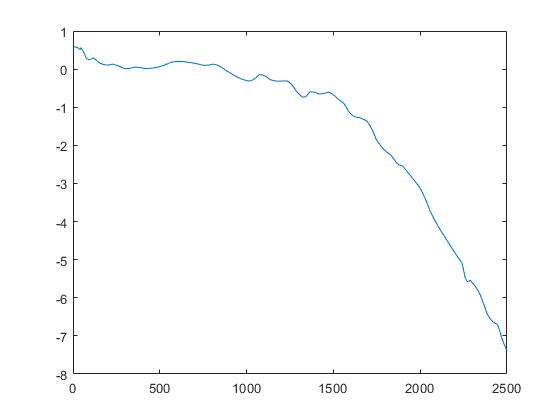

figure
plot(S21)

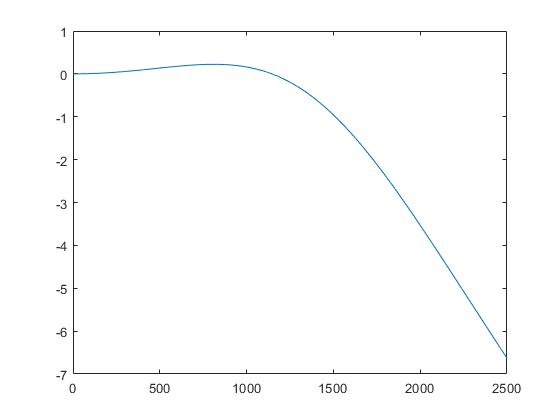

figure
x = optimresults.x;

load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;
% x = target;
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;

Ns1 = (1.904172485e-3./(x(4).*x(7)) + x(5).*x(6).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3))./(x(2)./x(3) + x(5).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3));
T1 = 293.15 + (7.5e-3.*2.464597008 - 1.904172485e-3).*Rth;
Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
Ss1 = ((x(1).*(7.5e-3 - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
Ps1 = x(4).*Ss1;
Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
M=20*log10(abs(H));
% H=((2i*pi*f).^2+(2i*pi*f)*Y+Z)./Z;
% M = 20*log10(abs(H));
plot(M)

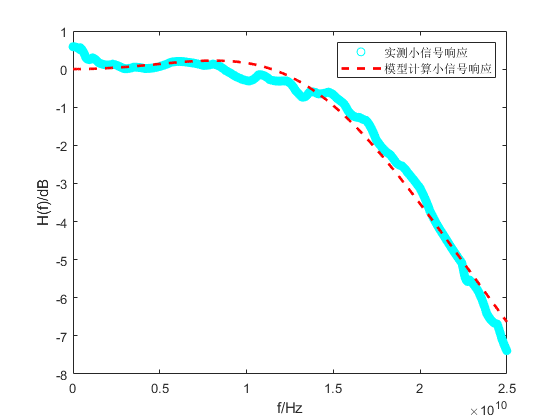

figure
plot(f, S21, 'oc')
hold on
plot(f, M, 'r--', 'LineWidth',2)
hold off
legend('实测小信号响应', '模型计算小信号响应')
xlabel('f/Hz')
ylabel('H(f)/dB')
saveas(gcf, 'fig15.png');

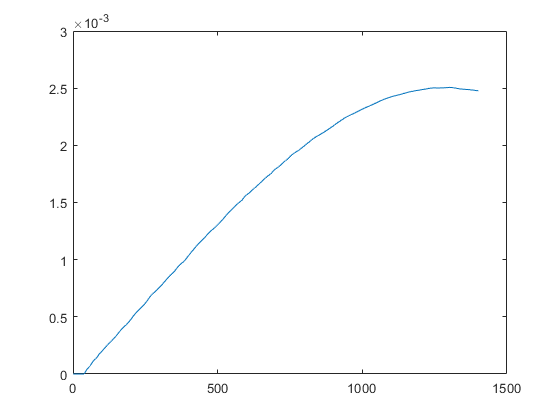

figure
plot(P)

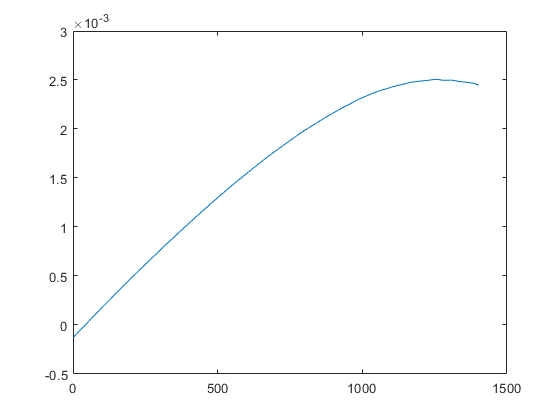

figure
x = optimresults.x;
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;

init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
plot(Ps)

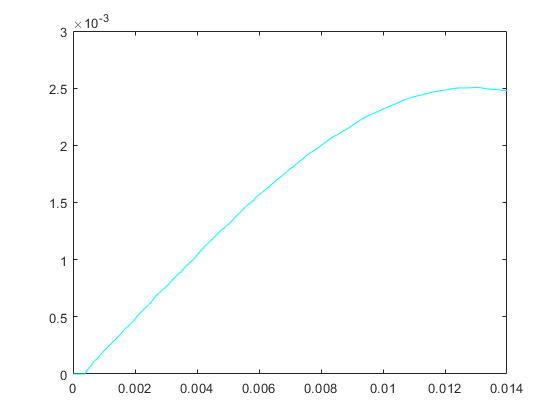

figure
plot(I, P, 'c')

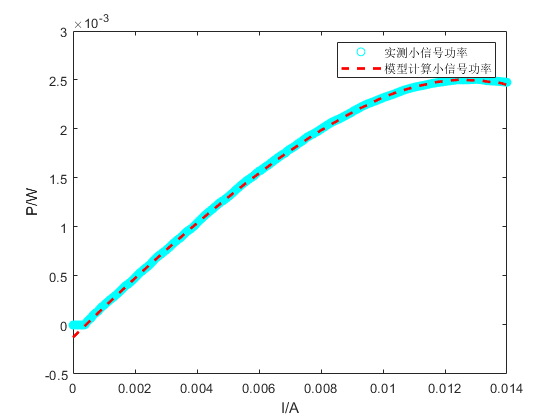

figure
plot(I, P, 'oc')
hold on
plot(I, Ps, 'r--', 'LineWidth',2)
hold off
legend('实测小信号功率', '模型计算小信号功率')
xlabel('I/A')
ylabel('P/W')
saveas(gcf, 'fig15_1.png');

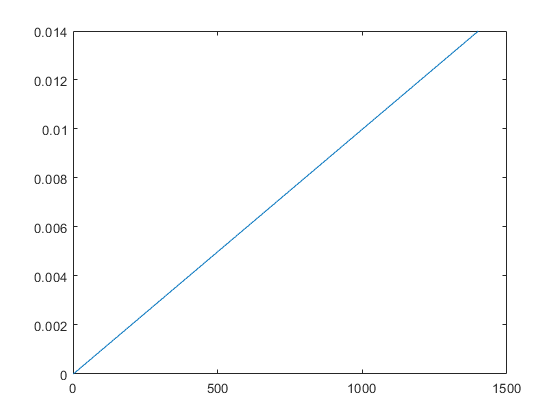

figure
plot(I)

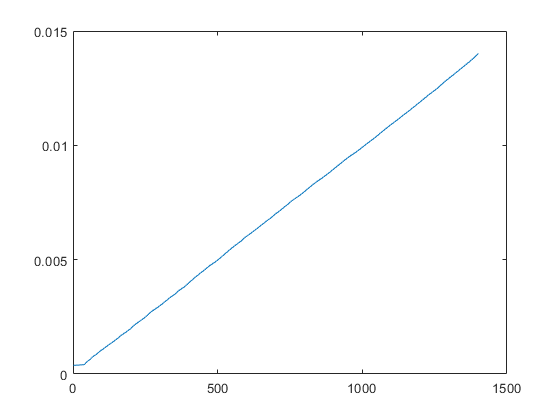

figure
x = optimresults.x;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
t1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff;
plot(t1)

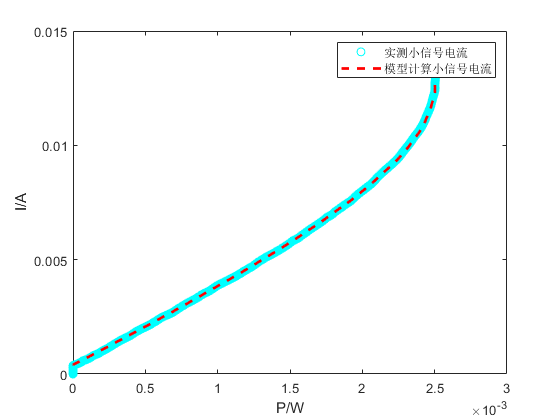

figure
plot(P, I, 'oc')
hold on
plot(P, t1, 'r--', 'LineWidth',2)
hold off
legend('实测小信号电流', '模型计算小信号电流')
xlabel('P/W')
ylabel('I/A')
saveas(gcf, 'fig15_2.png');

load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;

init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1.*4;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2.*10;

Ns1 = (1.904172485e-3./(x(4).*x(7)) + x(5).*x(6).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3))./(x(2)./x(3) + x(5).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3));
T1 = 293.15 + (7.5e-3.*2.464597008 - 1.904172485e-3).*Rth;
Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
Ss1 = ((x(1).*(7.5e-3 - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
Ps1 = x(4).*Ss1;
Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
% H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
% M=20*log10(abs(H));
H=((2i*pi*f).^2+(2i*pi*f)*Y+Z)./Z;
M = 20*log10(abs(H));
test3 = (M-S21)./10;

y2 = sum(test1.^2)+sum(test2.^2)+sum(test3.^2);

load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;

init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
x = init;
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;

Ns1 = (1.904172485e-3./(x(4).*x(7)) + x(5).*x(6).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3))./(x(2)./x(3) + x(5).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3));
T1 = 293.15 + (7.5e-3.*2.464597008 - 1.904172485e-3).*Rth;
Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
Ss1 = ((x(1).*(7.5e-3 - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
Ps1 = x(4).*Ss1;
Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
% H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
% M=20*log10(abs(H));
H=((2i*pi*f).^2+(2i*pi*f)*Y+Z)./Z;
M = 20*log10(abs(H));
test3 = (M-S21)./M;

y2 = sum(test1.^2)+sum(test2.^2)+sum(test3.^2);

fitness_5(x)

ans = 0.0639

target = [0.229535843579394 9.74930547730389e-06 1.35657742521920e-08  1.97291378335878e-08 1398983.42729603 87066.3421503811 1.16078659387274e-11 6.62869006156715e-09];